# Find Shortest Path Between People in Social Neighborhood

This example shows how to search a social neighborhood to find the shortest path between people, using the MATLAB® interface to Neo4j®. Assume that you have graph data that is stored on a Neo4j database which represents a social neighborhood. This database has seven nodes and eight relationships. Each node has only one unique property key `name` with a value ranging from `User1` through `User7`. Each relationship has type `knows`.

To find the shortest path between `User1` and `User7`, use the MATLAB interface to Neo4j and the [digraph](docid:matlab_ref.bun70tf) object. For details about the MATLAB interface to Neo4j, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

The local machine hosts the Neo4j database with port number `7474`, user name `neo4j`, and password `matlab`. For a visual representation of the data in the database, see this figure.

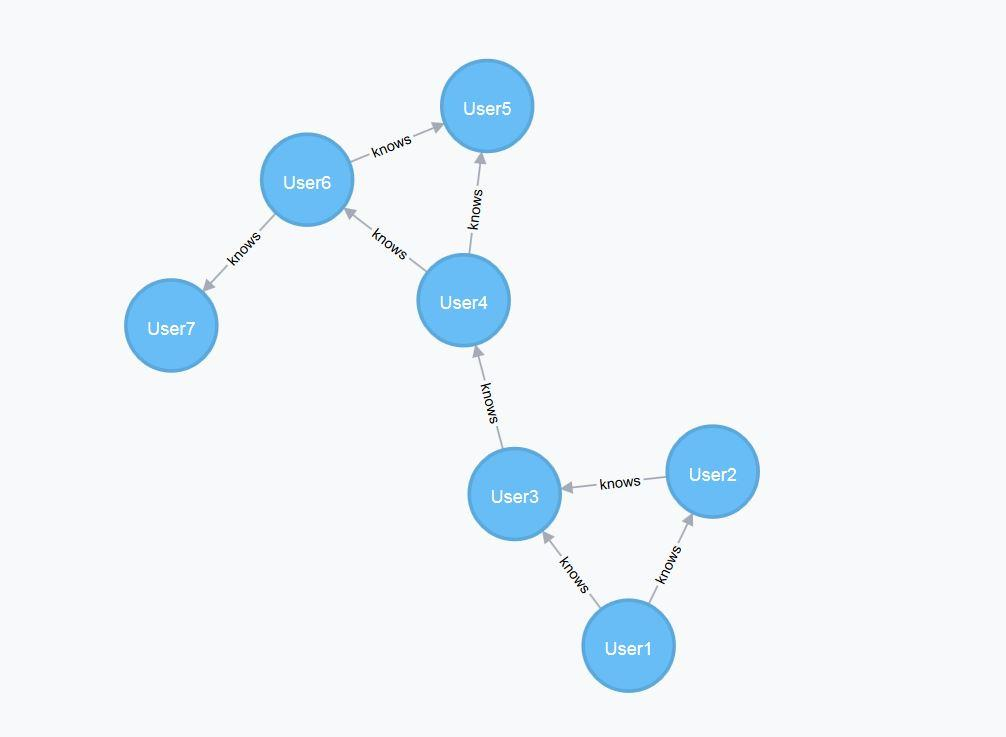

## Connect to Neo4j Database

Create a Neo4j connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Search Entire Graph

Find all the `Person` nodes and all the relationships associated with each `Person` node using `searchGraph`.

social_graphdata = searchGraph(neo4jconn,{'Person'})

## Convert Graph Data to Directed Graph

Using the table `social_graphdata.Nodes`, access the `name` property for each node that appears in the `NodeData` variable of the table.

Assign the table `social_graphdata.Nodes` to `nodestable`. 

nodestable = social_graphdata.Nodes

Assign the row names for each row in the table `nodestable` to `rownames`.

rownames = nodestable.Properties.RowNames

Access the `NodeData` variable from `nodestable` for each row. `nodedata` contains an array of structures.

nodedata = [nodestable.NodeData{rownames}]

To retrieve the `name` field from each structure, index into the array. `nodenames` is a cell array of character vectors that contains node names.

nodenames = {nodedata(:).name}

Create the `digraph` object `social_graph` using the `neo4jStruct2Digraph` function with the graph data stored in `social_graphdata` and the node names stored in `nodenames`.

social_graph = neo4jStruct2Digraph(social_graphdata,'NodeNames',nodenames)

To see a visual representation of the graph, create a figure that displays `social_graph`.

plot(social_graph,'EdgeLabel',social_graph.Edges.RelationType)

## Find Shortest Path

Find the shortest path between `User1` and `User7` using `shortestpath`.

[user1_to_user7,distance] = shortestpath(social_graph,'User1','User7')

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*